clc;
clear;
close all;

xyz_tb_1=readmatrix("E:\VScode\Proj_Molecular3D_V1\File\Output\CCC\XYZ_1.csv")

xyz_tb_1 =          0         0         0
         0         0    1.5080
    1.4215         0    2.0114
    1.0303         0   -0.3649
   -0.5152    0.8923   -0.3649
   -0.5152   -0.8923   -0.3649
   -0.5152   -0.8923    1.8728
   -0.5152    0.8923    1.8728
    2.1041   -0.1789    1.1767
    1.5444   -0.7893    2.7574


xyz_tb_2=readmatrix("E:\VScode\Proj_Molecular3D_V1\File\Output\CCC\XYZ_2.csv")

xyz_tb_2 =          0         0         0
         0         0    1.5080
    0.7108    1.2311    2.0114
    1.0303         0   -0.3649
   -0.5152    0.8923   -0.3649
   -0.5152   -0.8923   -0.3649
    0.5152   -0.8923    1.8728
   -1.0303   -0.0000    1.8728
    1.7416    1.2314    1.6481
    0.7102    1.2314    3.1044


xyz_tb_3=readmatrix("E:\VScode\Proj_Molecular3D_V1\File\Output\CCC\XYZ_3.csv")

xyz_tb_3 =          0         0         0
         0         0    1.5080
    0.7108    1.2310    2.0114
    1.0303         0   -0.3649
   -0.5152    0.8923   -0.3649
   -0.5152   -0.8923   -0.3649
    0.5151   -0.8923    1.8728
   -1.0303    0.0000    1.8728
    1.7416    1.2314    1.6481
    0.7103    1.2313    3.1044



bond_tb=readtable("../Output/CCC/BondTable.csv")

bond_tb = 4×3 table
    Seq1    Seq2    BondSym
    ____    ____    _______

     0       1       {'-'} 
     1       0       {'-'} 
     1       2       {'-'} 
     2       1       {'-'} 


nh_tb=readtable("E:\VScode\Proj_Molecular3D_V1\File\Output\CCC\MNodeTable.csv")

nh_tb = 3×9 table
    Seq    Element    IsAroma    CCount    CHCount    NHBC    CharSym    CharVal    MType
    ___    _______    _______    ______    _______    ____    _______    _______    _____

     0      {'C'}        0         1          3        1         0          0         1  
     1      {'C'}        0         2          2        2         0          0         1  
     2      {'C'}        0         1          3        1         0          0         1  


adj_list=bond2adj(bond_tb,"No",nh_tb)

nowhseq = 3

nowhnum = 3

nowarr =      1     3


nowarr =      1     3     4


nowarr =      1     3     4     5


values = 1×3 cell 数组
    {[1 3 4 5]}    {0×0 double}    {0×0 double}


nowarr =      0     2


nowhnum = 2

nowarr =      0     2     6


nowarr =      0     2     6     7


values = 1×3 cell 数组
    {[1 3 4 5]}    {[0 2 6 7]}    {0×0 double}


nowhnum = 3

nowarr =      1     8


nowarr =      1     8     9


nowarr =      1     8     9    10



adj_list =

  具有 3 个条目的 dictionary (cell ⟼ cell):

    {'0'} ⟼ {[1 3 4 5]}
    {'1'} ⟼ {[0 2 6 7]}
    {'2'} ⟼ {[1 8 9 10]}



%big_adj_list=bond2adj(bond_tb,"Yes",nh_tb)

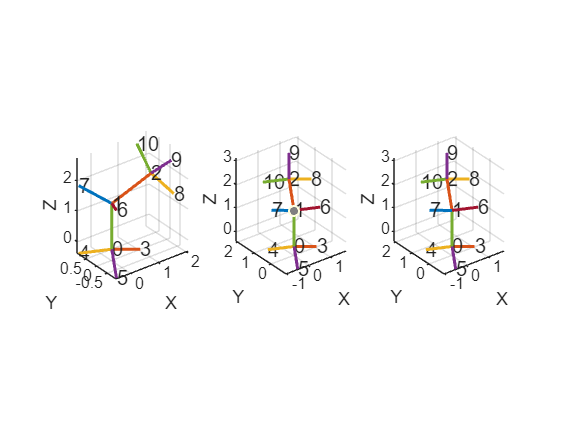

figure;
subplot(1,3,1);
moledraw(xyz_tb_1,adj_list)
subplot(1,3,2);
moledraw(xyz_tb_2,adj_list)
subplot(1,3,3);
moledraw(xyz_tb_3,adj_list)




% val=3
% val_lim=[-val val]
% xlim(val_lim)
% ylim(val_lim)
% zlim(val_lim)

function adj_list=bond2adj(bond_tb,Hcount,nh_tb)
nhc=size(nh_tb,1);
ac=sum(nh_tb{:,"CHCount"})+nhc;
oldseq=-1;
nowarr=[];
if Hcount=="Yes"
    keys=cell(1,ac);
    values=cell(1,ac);
else
    keys=cell(1,nhc);
    values=cell(1,nhc);
end

nowhseq=nhc
for i=1:size(bond_tb)
    nowseq=bond_tb{i,"Seq1"};
    if oldseq==nowseq
        nowarr=[nowarr,bond_tb{i,"Seq2"}]
    else
        %nowhseq=nowhseq+nowhnum;
        if i~=1
            nowhnum=nh_tb{oldseq+1,"CHCount"}
            for j=1:nowhnum
                nowarr=[nowarr,nowhseq]
                nowhseq=nowhseq+1;
            end
            nowarr=sort(nowarr);
            values{1,oldseq+1}=nowarr
        end
        nowarr=[bond_tb{i,"Seq2"}];
        oldseq=nowseq;
        keys{1,nowseq+1}=num2str(nowseq);
    end
end
nowhnum=nh_tb{oldseq+1,"CHCount"}
for j=1:nowhnum
    nowarr=[nowarr,nowhseq]
    nowhseq=nowhseq+1;
end
nowarr=sort(nowarr);
values{1,oldseq+1}=nowarr;
% if Hcount=="Yes"
%     nownhseq=0;
%     nowhcount=0;
%     for i=(nhc+1):ac
%         keys{1,i}=i-1;
%         values{1,i}=nownhseq;
%         if nowhcount==nh_tb{nownhseq+1,"CHCount"}
%             nowhseq=nowhseq+1;
%             nowhcount=0;
%         end
%     end
% end
adj_list=dictionary(keys,values);
end